# Condition analysis processing

### Analyze the whisking and seperate the neuronal data into the experimntal conditions

**Load ephys exp**

clear 
clc
close all

experiment = loadExp

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB111_715'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [5481×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
        

Preprocess the whisking data

% extract whisking data to a variable
whisking = experiment.Whisking.Raw

whisking = 1×899831 single row vector
1.0e+04 *

    0.0177    0.0177    0.0985    0.0267    0.0562    0.0589    0.0489    0.0785    0.0229   -0.0785    0.0081   -0.1555    0.1168    0.0385    0.0066   -0.0438   -0.3045   -0.2014   -0.2352   -0.2353   -0.1490   -0.1711    0.0982    0.1103   -0.0887   -0.1196    0.0091   -0.0278    0.2988    0.0400   -0.2391   -0.0956    0.0229   -0.2816   -0.2448   -0.1379   -0.0359    0.2172    0.1505    0.1284    0.0583   -0.0048   -0.0153    0.0411    0.0527   -0.0632   -0.0574    0.2122    0.0114    0.0433


% Build band pass filter
Fs = 150; % sf of video 400 frames per second
%whisking = normalize(whisking,'range',[0 1])
whisking(1:2) = whisking(2:3);
%[b,a] = butter(5,[0.1,70]/75,'bandpass');
%whisking_filtered = filtfilt(b,a,double(whisking));
%whisking_filtered = normalize(whisking_filtered,'range',[0 1])
% envelope whisking data
%[whisk_envlope,~] = envelope(whisking);

% smooth whisking data
sigma = 0.2 * Fs; % 200ms kernel
smoothedEnv = imgaussfilt(whisking, sigma);


Identify Whisking events

% detrmine threshold 
thershold = 1.5*std(smoothedEnv())+min(smoothedEnv)

thershold = single
2.4339e+03

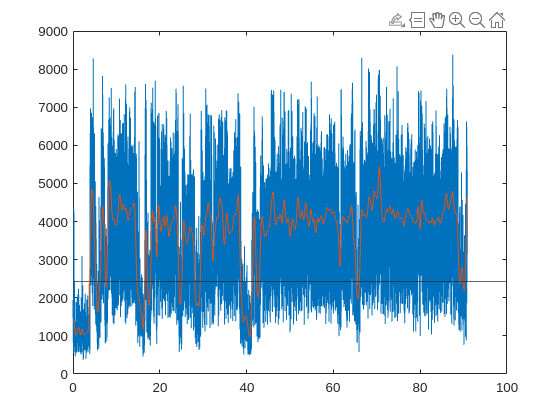

% optional plots
figure; plot([1:length(whisking)]/150,whisking) % filtered data
%figure; plot(whisking_filtered) % filtered data
%figure; plot(whisk_envlope) % envelope
hold on; plot([1:length(whisking)]/150,smoothedEnv) % smoothed data
yline(thershold)


% get times above threshold
whiskingBinary = smoothedEnv > thershold;
cc = bwconncomp(whiskingBinary); % seperate events to continuous ones

% find the whisking epochs and classifay them according to duration
epochs = zeros(cc.NumObjects, 3); % structure: [start, end, type]
minumumDuration = 0.5; % deterine the minumum amountfor epoch
longEpoch = 5; % determine the cut off between long and short epochs

for i = 1:cc.NumObjects
    epochs(i, 1) = cc.PixelIdxList{i}(1);   % start
    epochs(i, 2) = cc.PixelIdxList{i}(end); % end
    duration = (epochs(i, 2) - epochs(i, 1)) / Fs;
    
    if duration > 0.5 && duration <= 5
        epochs(i, 3) = 1; % Short epoch
    elseif duration > 5
        epochs(i, 3) = 2; % Long epoch
    end
end

visualize epochs

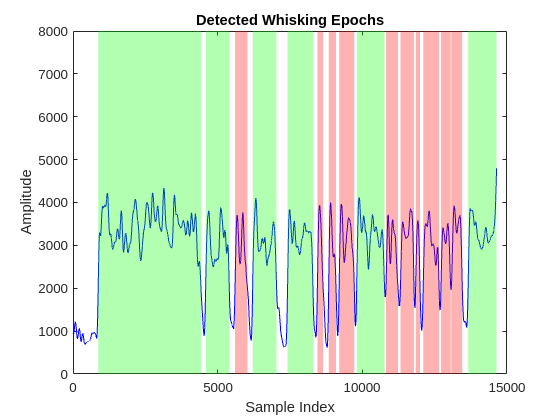

figure;
plot(smoothedEnv, 'b'); % Original signal
hold on;
maxY = 8000;
for i = 1:size(epochs, 1)
    startX = epochs(i, 1);
    endX = epochs(i, 2);
    
    if epochs(i, 3) == 1
        fill([startX, endX, endX, startX], [0, 0, maxY, maxY], 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    elseif epochs(i, 3) == 2
        fill([startX, endX, endX, startX], [0, 0, maxY, maxY], 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    end
end

hold off;
xlabel('Sample Index');
ylabel('Amplitude');
title('Detected Whisking Epochs');

if epochs(end,2) > length(experiment.Cams.whisking.csv_aligned_frames)
    epochs(end,2) = length(experiment.Cams.whisking.csv_aligned_frames)
end

epochs =            1        1386           1
       24784       24940           0
       31242       33716           2
       35500       35565           0
       45628       45752           0
       49349       49672           1
       57388       57463           0
       57657       58628           1
       59316       59467           0
       59613       59956           1


% align the whisking time wpochs with the ephys samples
epochsEphys = [experiment.Cams.whisking.csv_aligned_frames(epochs(1:end,1:2)),epochs(1:end,3)];

% add the epochs to the experiment data 
experiment.Whisking.smoothed = smoothedEnv;
experiment.Whisking.all = epochsEphys;
experiment.Whisking.short = epochsEphys(epochsEphys(:,3)==1,1:2)

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB111_715'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [5481×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
        

experiment.Whisking.long = epochsEphys(epochsEphys(:,3)==2,1:2)

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB111_715'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [5481×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
        

% Divide whisking epochs to the conditions and dvide the units data to the
% conditions
experiment.conditionVector = experiment.getConVector()

conditionV = struct with fields:
      aluminumEpochs: [19×2 int64]
         mutedEpochs: [12×2 int64]
           nonEpochs: [10×2 int64]
    noWhiskingEpochs: [313×2 int64]
            aluminum: [8855022 8855023 8855024 8855025 8855026 8855027 8855028 8855029 8855030 8855031 8855032 8855033 8855034 8855035 8855036 8855037 8855038 8855039 8855040 8855041 8855042 8855043 8855044 8855045 8855046 8855047 8855048 8855049 … ]


conditionV = struct with fields:
      aluminumEpochs: [19×2 int64]
         mutedEpochs: [12×2 int64]
           nonEpochs: [10×2 int64]
    noWhiskingEpochs: [313×2 int64]
            aluminum: [8855022 8855023 8855024 8855025 8855026 8855027 8855028 8855029 8855030 8855031 8855032 8855033 8855034 8855035 8855036 8855037 8855038 8855039 8855040 8855041 8855042 8855043 8855044 8855045 8855046 8855047 8855048 8855049 … ]
               muted: [11197413 11197414 11197415 11197416 11197417 11197418 11197419 11197420 11197421 11197422 11197423 11197424 11197425 11197426 11197427 11197428 11197429 11197430 11197431 11197432 11197433 11197434 11197435 11197436 11197437 … ]


conditionV = struct with fields:
      aluminumEpochs: [19×2 int64]
         mutedEpochs: [12×2 int64]
           nonEpochs: [10×2 int64]
    noWhiskingEpochs: [313×2 int64]
            aluminum: [8855022 8855023 8855024 8855025 8855026 8855027 8855028 8855029 8855030 8855031 8855032 8855033 8855034 8855035 8855036 8855037 8855038 8855039 8855040 8855041 8855042 8855043 8855044 8855045 8855046 8855047 8855048 8855049 … ]
               muted: [11197413 11197414 11197415 11197416 11197417 11197418 11197419 11197420 11197421 11197422 11197423 11197424 11197425 11197426 11197427 11197428 11197429 11197430 11197431 11197432 11197433 11197434 11197435 11197436 11197437 … ]
                 non: [7758279 7758280 7758281 7758282 7758283 7758284 7758285 7758286 7758287 7758288 7758289 7758290 7758291 7758292 7758293 7758294 7758295 7758296 7758297 7758298 7758299 7758300 7758301 7758302 7758303 7758304 7758305 7758306 … ]


conditionV = struct with fields:
      aluminumEpochs: [19×2 int64]
         mutedEpochs: [12×2 int64]
           nonEpochs: [10×2 int64]
    noWhiskingEpochs: [313×2 int64]
            aluminum: [8855022 8855023 8855024 8855025 8855026 8855027 8855028 8855029 8855030 8855031 8855032 8855033 8855034 8855035 8855036 8855037 8855038 8855039 8855040 8855041 8855042 8855043 8855044 8855045 8855046 8855047 8855048 8855049 … ]
               muted: [11197413 11197414 11197415 11197416 11197417 11197418 11197419 11197420 11197421 11197422 11197423 11197424 11197425 11197426 11197427 11197428 11197429 11197430 11197431 11197432 11197433 11197434 11197435 11197436 11197437 … ]
                 non: [7758279 7758280 7758281 7758282 7758283 7758284 7758285 7758286 7758287 7758288 7758289 7758290 7758291 7758292 7758293 7758294 7758295 7758296 7758297 7758298 7758299 7758300 7758301 7758302 7758303 7758304 7758305 7758306 … ]
          noWhisking: [149086 149087 149088 149089 149090 149091 149092 

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB111_715'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [5481×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
        

nonWhiskingCondition.aluminumEpochs = getIntersct(experiment,1);
nonWhiskingCondition.attenuatedEpochs = getIntersct(experiment,2);
nonWhiskingCondition.noObjectEpochs = getIntersct(experiment,3);
nonWhiskingCondition.aluminum = condVector(nonWhiskingCondition.aluminumEpochs);
nonWhiskingCondition.attenuated = condVector(nonWhiskingCondition.attenuatedEpochs);
nonWhiskingCondition.noObject = condVector(nonWhiskingCondition.noObjectEpochs);
experiment.conditionVector.noWhiskingCondition = nonWhiskingCondition

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB111_715'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [5481×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 0.0016 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
        

experiment.Units.perCondition = experiment.unitTimesCondition()

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1303×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [-0.0011 -0.0011 -0.0011 -0.0011 -0.0011 -0.0011 -0.0011 -0.0010 -0.0010 -0.0010 -0.0010 -0.0010 -0.0010 -9.9569e-04 -9.8688e-04 -9.7807e-04 -9.6927e-04 -9.6047e-04 -9.5169e-04 -9.4292e-04 -9.3416e-04 -9.2542e-04 -9.1669e-04 … ]
            evokedEvents: []
         conditionVector: [1×1 struct]
                Wh

Visulaize all experimntal conditions

colorPallete
figure;
plot(experiment.Cams.whisking.csv_aligned_frames,experiment.Whisking.smoothed(1:length(experiment.Cams.whisking.csv_aligned_frames)), 'b'); % Original signal
hold on;
maxY = 8000;
plot((experiment.sound.smoothed/50)+100)
most_events = max([length(experiment.conditionVector.aluminumEpochs), ...
    length(experiment.conditionVector.mutedEpochs) ...
    ,length(experiment.conditionVector.nonEpochs) ...
    ,length(experiment.conditionVector.noWhiskingEpochs)])

most_events = 313

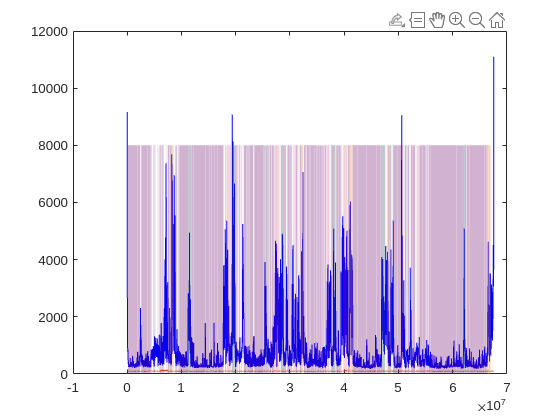

for i = 1:most_events
    try
        startXAl = experiment.conditionVector.aluminumEpochs(i, 1);
        endXAl = experiment.conditionVector.aluminumEpochs(i, 2);
        fill([startXAl, endXAl, endXAl, startXAl], [0, 0, maxY, maxY],'r','FaceColor',colorBen.aluminum,'FaceAlpha',0.2,'EdgeColor','none');
    end
    try
        startXAt = experiment.conditionVector.mutedEpochs(i, 1);
        endXAt = experiment.conditionVector.mutedEpochs(i, 2);
        fill([startXAt, endXAt, endXAt, startXAt], [0, 0, maxY, maxY],'b','FaceColor',colorBen.muted, 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    end
    try
        startXNo = experiment.conditionVector.nonEpochs(i, 1);
        endXNo = experiment.conditionVector.nonEpochs(i, 2);
        fill([startXNo, endXNo, endXNo, startXNo], [0, 0, maxY, maxY],'y','FaceColor',colorBen.non, 'FaceAlpha', 0.3, 'EdgeColor', 'none');

    end
    try
        startXNW = experiment.conditionVector.noWhiskingEpochs(i, 1);
        endXNW = experiment.conditionVector.noWhiskingEpochs(i, 2);
        fill([startXNW, endXNW, endXNW, startXNW], [0, 0, maxY, maxY],'y','FaceColor',colorBen.purple, 'FaceAlpha', 0.3, 'EdgeColor', 'none');

    end
end

% extract FR across conditions for the table
FR_aluminum = experiment.Units.perCondition.aluminum.FR

FR_aluminum =     1.1087
    1.0249
    1.4684
    1.9365
    0.2661
    0.6652
    0.3055
    0.4632
    0.5174
   11.9489


FR_attenuated = experiment.Units.perCondition.muted.FR

FR_attenuated =     1.8074
    1.8823
    0.7814
    2.2517
    0.0499
    0.4668
    0.3819
    0.3345
    3.2578
   12.7091


FR_noObject = experiment.Units.perCondition.non.FR

FR_noObject =     1.8859
    1.3421
    0.7855
    2.0004
    0.0461
    0.3959
    0.3705
    0.3482
    1.4343
   10.0958


FR_NoWhisking = experiment.Units.perCondition.noWhisking.FR

FR_NoWhisking =     0.7073
    1.3190
    0.9697
    1.9777
    0.0591
    0.2746
    1.2461
    0.5179
    0.6847
    8.9726


% extract sub conditions for no whisking
FR_NoWhisking_aluminum = experiment.Units.perCondition.noWhisking.aluminum.FR

FR_NoWhisking_aluminum =     0.6810
    0.8987
    1.2906
    2.2289
    0.0515
    0.2573
    1.4688
    0.6295
    0.2375
    9.0384


FR_NoWhisking_attenuated = experiment.Units.perCondition.noWhisking.attenuated.FR

FR_NoWhisking_attenuated =     0.5571
    1.8455
    0.3482
    1.6626
    0.0609
    0.1828
    1.1839
    0.2699
    1.8977
   10.0281


FR_NoWhisking_noObject = experiment.Units.perCondition.noWhisking.noObject.FR

FR_NoWhisking_noObject =     0.7007
    1.8028
    0.6349
    1.7489
    0.0180
    0.1437
    0.8625
    0.3534
    0.5031
    8.3191


[AluminumSDF,AluminumBinnedFR,AluminumSTD,aluminumSamples] = getSDFs(experiment.conditionVector.aluminumEpochs,experiment.Units.perCondition.aluminum.times,20)

AluminumSDF = 24×1 cell array
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}


AluminumBinnedFR = 24×1 cell array
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}
    {202943×1 double}


AluminumSTD =    41.8806
   30.6356
   37.2801
   13.8321
         0
   19.9991
   13.1885
   13.8321
   10.2161
   75.0945


aluminumSamples = 202943×1 int64 column vector
   5007465
   5007495
   5007525
   5007555
   5007585
   5007615
   5007645
   5007675
   5007705
   5007735


[AttenuatedSDF,AttenuatedBinnedFR,AttenuatedSTD,attenuatedSamples] = getSDFs(experiment.conditionVector.mutedEpochs,experiment.Units.perCondition.muted.times,20)

AttenuatedSDF = 24×1 cell array
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}


AttenuatedBinnedFR = 24×1 cell array
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}
    {400571×1 double}


AttenuatedSTD =    52.0243
   34.3741
   30.6356
   31.4743
    7.2241
   30.0635
   21.6678
   22.8392
   71.6948
  108.9021


attenuatedSamples = 400571×1 int64 column vector
   12338912
   12338942
   12338972
   12339002
   12339032
   12339062
   12339092
   12339122
   12339152
   12339182


[NoObjectSDF,NoObjectBinnedFR,noObjectSTD,NoObjectSamples] = getSDFs(experiment.conditionVector.nonEpochs,experiment.Units.perCondition.non.times,20)

NoObjectSDF = 24×1 cell array
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}


NoObjectBinnedFR = 24×1 cell array
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}
    {628864×1 double}


noObjectSTD =    44.8781
   59.4260
   23.2627
   29.7526
         0
    9.9214
    9.9214
   25.2879
   34.3502
   91.8855


NoObjectSamples = 628864×1 int64 column vector
   6676339
   6676369
   6676399
   6676429
   6676459
   6676489
   6676519
   6676549
   6676579
   6676609


[NoWhiskingSDF,NoWhiskingBinnedFR,NoWhiskingSTD,NoWhiskingSamples] = getSDFs(experiment.conditionVector.noWhiskingEpochs,experiment.Units.perCondition.noWhisking.times,20)

NoWhiskingSDF = 24×1 cell array
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}


NoWhiskingBinnedFR = 24×1 cell array
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}
    {575396×1 double}


NoWhiskingSTD =    24.3725
   47.0156
    7.3506
   16.4346
    7.3506
   25.4555
   26.4942
    7.3506
   23.2388
   82.5541


NoWhiskingSamples = 575396×1 int64 column vector
   4711818
   4711848
   4711878
   4711908
   4711938
   4711968
   4711998
   4712028
   4712058
   4712088


% Create a reference table for the units 
unitID = [experiment.Units.good.id;experiment.Units.mua.id]

unitID =     69
    71
    84
    98
   154
   179
   181
   193
   214
    23


unitType = categorical([repmat("good",length(experiment.Units.good.id),1);repmat("mua",length(experiment.Units.mua.id),1)])

unitType = 24×1 categorical array
     good 
     good 
     good 
     good 
     good 
     good 
     good 
     good 
     good 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 


Session = repmat({experiment.experiment_ID},length(unitID),1)

Session = 24×1 cell array
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}
    {'FVB103_757'}


referance_table = table(unitID,unitType,Session,FR_aluminum,FR_attenuated,FR_noObject,FR_NoWhisking, ...
    FR_NoWhisking_aluminum,FR_NoWhisking_attenuated,FR_NoWhisking_noObject ...
    ,AluminumSDF,AttenuatedSDF,NoObjectSDF,NoWhiskingSDF,AluminumBinnedFR,AttenuatedBinnedFR, ...
    NoObjectBinnedFR,NoWhiskingBinnedFR,AluminumSTD,AttenuatedSTD,noObjectSTD,NoWhiskingSTD)

referance_table = 24×22 table
    unitID    unitType       Session        FR_aluminum    FR_attenuated    FR_noObject    FR_NoWhisking    FR_NoWhisking_aluminum    FR_NoWhisking_attenuated    FR_NoWhisking_noObject       AluminumSDF         AttenuatedSDF         NoObjectSDF         NoWhiskingSDF      AluminumBinnedFR     AttenuatedBinnedFR    NoObjectBinnedFR     NoWhiskingBinnedFR    AluminumSTD    AttenuatedSTD    noObjectSTD    NoWhiskingSTD
    ______    ________    ______________    ___________    _____________    ________

filename = [experiment.experiment_ID,'.mat']

filename = 'FVB103_757.mat'


tblFileName = ['condUnits_',filename]

tblFileName = 'condUnits_FVB103_757.mat'

% save(filename,'experiment','-v7.3')
% save(tblFileName,'referance_table','adjustedSamples','conditionVector')


adjustedSamples.Aluminum = aluminumSamples;
adjustedSamples.Attenuated = attenuatedSamples;
adjustedSamples.noObject = NoObjectSamples;
adjustedSamples.NoWhisking = NoWhiskingSamples;

conditionVector = experiment.conditionVector

conditionVector = struct with fields:
         aluminumEpochs: [11×2 int64]
            mutedEpochs: [14×2 int64]
              nonEpochs: [27×2 int64]
       noWhiskingEpochs: [49×2 int64]
               aluminum: [5007465 5007466 5007467 5007468 5007469 5007470 5007471 5007472 5007473 5007474 5007475 5007476 5007477 5007478 5007479 5007480 5007481 5007482 5007483 5007484 5007485 5007486 5007487 5007488 5007489 5007490 5007491 5007492 … ]
                  muted: [12338912 12338913 12338914 12338915 12338916 12338917 12338918 12338919 12338920 12338921 12338922 12338923 12338924 12338925 12338926 12338927 12338928 12338929 12338930 12338931 12338932 12338933 12338934 12338935 12338936 … ]
                    non: [6676339 6676340 6676341 6676342 6676343 6676344 6676345 6676346 6676347 6676348 6676349 6676350 6676351 6676352 6676353 6676354 6676355 6676356 6676357 6676358 6676359 6676360 6676361 6676362 6676363 6676364 6676365 6676366 … ]
             noWhisking: [4711818 4711819 47118

alignedTimes = experiment.timeStamp

alignedTimes = struct with fields:
           ephys: [8361 28790259 63322149]
         avisoft: [190061 240067332 527866870]
      alignedAvi: [NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ]
    alignedEphys: [NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ]


save(filename,'experiment','-v7.3')

save(tblFileName,'referance_table','adjustedSamples','conditionVector','alignedTimes',"-append")      


function [SDFs,unitVecBinned,unitSTD,samplesBinned] = getSDFs(conditionEpochs,unitsStruct,sigma)
% use condition spike times and condition epochs to generate a SDF for all
% units. sigma should be in units of ms.
    SDFs = cell(length(unitsStruct),1);
    edges = [-3*sigma:1:3*sigma];
    kernel = normpdf(edges,0,sigma)*1000;
    binSize = 30;
    unitVecBinned = cell(length(unitsStruct),1);
    unitSTD = [];
    samplesBinned = [];
    
    for ep = 1:size(conditionEpochs)
        discard = 0;
        epTimes = [conditionEpochs(ep,1):conditionEpochs(ep,2)];
        indexBuffer = buffer(epTimes, 30, 0,"nodelay");
        if any(indexBuffer(:,end) == 0)
            indexBuffer(:,end) = [];
            discard = 1;
        end
        samplesBinned = [samplesBinned,indexBuffer(1,:)];
        for un = 1:length(unitsStruct)
            %unitVbinned = [];
            %SDFV = [];
            unitTrain = unitsStruct{un};
            unitTemp = ismember(epTimes,unitTrain);
            unitBuffer = buffer(unitTemp, 30, 0,"nodelay");
            binnedSpikeTrain = sum(unitBuffer);
            if discard == 1
                binnedSpikeTrain(end) = [];
            end
            SDFtemp = conv(binnedSpikeTrain,kernel,'same');
            SDFs{un,1} = [SDFs{un,1};SDFtemp'];
            unitVecBinned{un,1} = [unitVecBinned{un,1};binnedSpikeTrain'];
            unitSTD(un) = std(binnedSpikeTrain*1000);
        end
    end
    unitSTD = unitSTD';
    samplesBinned = samplesBinned';
end
function intersections = getIntersct(experiment,condType)
                intersections = [];
                condA = experiment.conditionVector.noWhiskingEpochs;
                condB = experiment.Conditions.all_changesClean(experiment.Conditions.classificationCleaned == condType,:);
                for i = 1:size(condA,1)
                    for j = 1:size(condB,1)
                        % Check if condB(j,:) is entirely within condA(i,:)
                        if condB(j,1) >= condA(i,1) && condB(j,2) <= condA(i,2)
                            intersections = [intersections; condB(j,1) condB(j,2)];
                            % Check if condA(i,:) is entirely within condB(j,:)
                        elseif condA(i,1) >= condB(j,1) && condA(i,2) <= condB(j,2)
                            intersections = [intersections; condA(i,1) condA(i,2)];
                            % Check for any other overlaps
                        else
                            overlapStart = max(condA(i,1), condB(j,1));
                            overlapEnd = min(condA(i,2), condB(j,2));
                            if overlapStart < overlapEnd
                                intersections = [intersections; overlapStart overlapEnd];
                            end
                        end
                    end
                end
end


function intersectVector = condVector(conditionVect)
intersectVector = [];
for i = 1:size(conditionVect,1)
    intersectVector = [intersectVector, conditionVect(i,1):conditionVect(i,2)];
end
end
% 
%     for un = 1:length(unitsStruct)
%         unitVbinned = [];
%         SDFV = [];
%         unitTrain = unitsStruct{un};
%         for ep = 1:size(conditionEpochs)
%             epTimes = [conditionEpochs(ep,1):conditionEpochs(ep,2)];
%             unitTemp = ismember(epTimes,unitTrain);
% 
%             paddedSpiketrain = [unitTemp,zeros(1,padding)];
%             binnedSpikeTrain = sum(reshape(paddedSpiketrain,binSize,[]));
%             unitVbinned = [unitVbinned,binnedSpikeTrain];
%             SDFtemp = conv(binnedSpikeTrain,kernel,'same');
%             SDFV = [SDFV,SDFtemp];
%         end
%         SDFs{un,1} = SDFV';
%         unitVecBinned{un,1} = unitVbinned';
%         unitSTD(un) = std(unitVbinned*1000);
%     end
%     unitSTD = unitSTD';
%     samplesBinned = samplesBinned';
% end


